# Basic Plugins

Our entry point is the Audio System Toolbox documentation

doc audio

Specifically, go through this tutorial to create your first plugin, step by step, with annotations

web(fullfile(docroot, 'audio/gs/design-an-audio-plugin.html?container=jshelpbrowser'))

(If something goes wrong in editing, the final file myEchoPlugin.m is provided in this repository)

## Test Real-Time Audio in MATLAB

The easiest way of testing an audio plugin is by using [audioTestBench](https://se.mathworks.com/help/releases/R2019a/audio/ref/audiotestbench-app.html) (see also a [Walkthrough](https://se.mathworks.com/help/releases/R2019a/audio/ug/audio-test-bench-walkthrough.html))

audioTestBench myEchoPlugin;

A better practice is create the object first and run the audioTestBench with an instance of this object

clear % The next line catches possible instantiation errors 
myE = myEchoPlugin 
audioTestBench myE;

If the audioTestBench is too heavy on your system, you can run it once and create a test script.

% The following is a Test bench script for 'myEchoPlugin'.
% Generated by Audio Test Bench on 30-Mar-2019 09:00:24 +0100.
% See myEchoTestBenchScript for more info, we use it below.

After this, you can run your real-time script from the command line:

myEchoTestBenchScript 

Of course, this test script can also be manually created, see 

web(fullfile(docroot, 'audio/gs/real-time-audio-in-matlab.html?container=jshelpbrowser'))

## Optimize Latency in Your System

If you are hearing glitches, drop-outs, or your system feels very loaded even after scripting, please try out these:

web(fullfile(docroot, 'audio/gs/audio-io-buffering-latency-and-throughput.html?container=jshelpbrowser'))

Especially Windows users may want to consider ASIO drivers. If you have a sound device that comes with ASIO 

asiosettings

else install universal drivers from [http://www.asio4all.org/](http://www.asio4all.org/) 

# Other Basic Plugins

The audioPlugin `class` is shown on the right, and it consists from `properties` and `methods`.

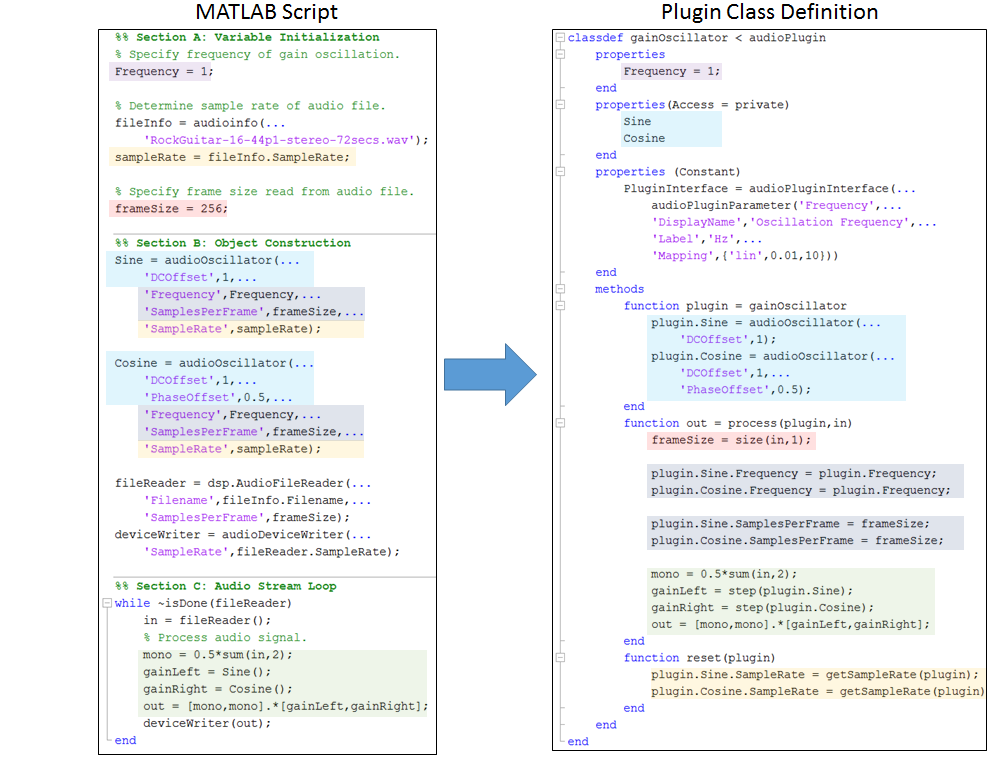

## Audio Pass-Thru

Our first example has only a `process(~,in) `for passing through the incoming audio buffer.

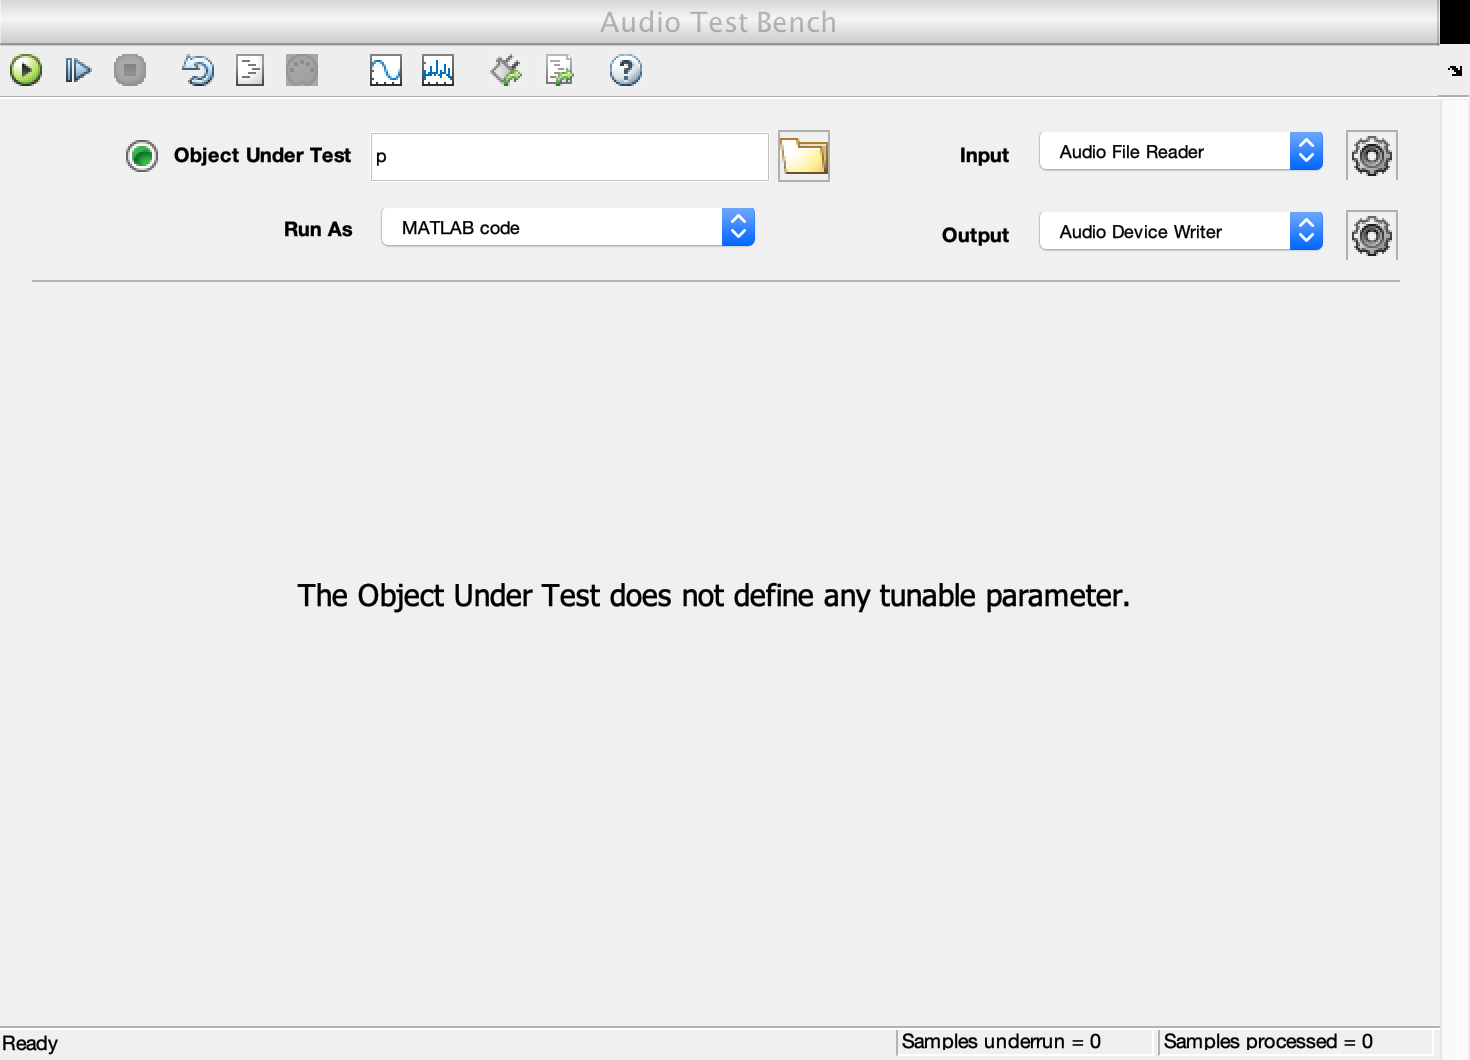

edit myWire.m;
p = myWire;
audioTestBench p;

There is not much to test in this plugin, but we can check the functionality of the scopes.

## First Parameter: Stereo Width

Remember how we split a stereo signal to the mid / side channels in `stereoImager() `from Chapter 9 of HackAudio?

edit stereoImager.m;

Now we will contol the width with a slider in real time. For this, we create a new class `myWidth `and define the slider (as a `Constant PluginInterface`) property. 

Save this snippet at myWidth.m and test it on audioTestBench: the slider should act like a gain control.

Now change the process method of myWidth.m as follows

        function out = process (plugin, in)
           mid = 0.5*(in(:,1) + in(:,2));
           sid = 0.5*(in(:,1) - in(:,2));
           sid = plugin.Width * sid;
           out = [mid+sid mid-sid];
        end

Reload the myWidth in audioTestBench and test if the slider is working as width expander.

### Exercise: myPanner

Can you convert myWidth to a linear panner plugin? Enter your new code here:

        % HINT: edit myFilePan.m